# Radio FM Stereo syntetyczny

fs = 1e6;         % sampling frequency
N  = 20551993;         % number of samples (IQ)
fc = 250e3;        % central frequency of MF station

f = fopen('stereo_samples_fs1000kHz_LR_IQ.mat');
s = fread(f, 2*N, 'uint8');
fclose(f);

s = s-127;

%% IQ --> complex
wideband_signal = s(1:2:end) + sqrt(-1)*s(2:2:end); clear s;

%% Extract carrier of selected service, then shift in frequency the selected service to the baseband
wideband_signal_shifted = wideband_signal .* exp(-1i*2*pi*fc/fs*[0:N-1]');

%% Filter out the service from the wide-band signal

Astop = 40; % t�umienie w pa�mie zaporowym 
Fstop = 80e3 + 2000; % od tego moemntu t�umie
Fpass = 80e3; %przepuszaczna mx czestotliwo��
Apass = 3;

LowPassSpec = fdesign.lowpass(Fpass, Fstop, Apass, Astop,3.2e6);
LowPassFilter1 = design(LowPassSpec,'ellip');

[b, a] = tf(LowPassFilter1);
wideband_signal_filtered = filter( b, a, wideband_signal_shifted );

%% Down-sample to service bandwidth - bwSERV = new sampling rate
bwSERV = 80e3; bwAUDIO = 16e3;   
x = decimate(wideband_signal_filtered,20);
fs = fs/20;
%% FM demodulation
dx = x(2:end).*conj(x(1:end-1));
y = atan2( imag(dx), real(dx) );

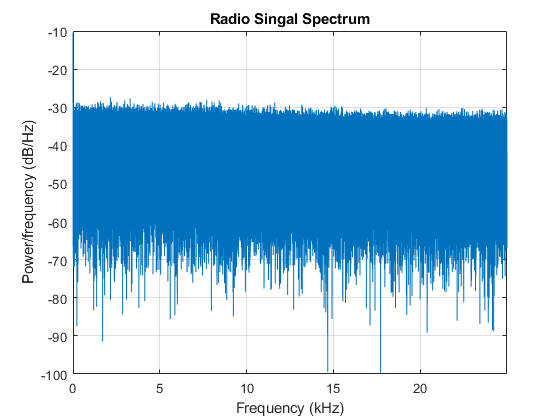

% plot input power spectral density 
figure
periodogram(y,rectwin(length(y)),length(y),fs)
title('Radio Singal Spectrum');

#### L-R

%[fpr,~] = max(periodogram(pilot.y,rectwin(length(pilot.y)),length(pilot.y),fs));
fpr = 18994;

% czemu tak?
%stereo.b = fir1(N,[(fpr)/bwSERV (3*fpr)/bwSERV],blackmanharris(N+1));
stereo.b = fir1(N,[(21e3)/bwSERV (55e3)/bwSERV],blackmanharris(N+1));

[stereo.h,stereo.f] = freqz(stereo.b,1,0.1:0.5:80e3,80e3);
figure
hold on
plot(2*stereo.f,20*log(abs(stereo.h)),[0 80e3],[-60 -60],'b-')
plot([23e3 23e3],[-350 10],'g-');
plot([53e3 53e3],[-350 10],'g-');
plot([fpr fpr],[-350 10],'r-');
plot([fpr*3 fpr*3],[-350 10],'r-');
xlim([10e3 65e3]);
ylim([-350 10])
title('Filtr stereo fpl - 3fpl');


y_stereo = filter(stereo.b,1,y);
figure
periodogram(y_stereo,rectwin(length(y_stereo)),length(y_stereo),fs)
title('stereo signal');